close all;
clear;
clc;


## Question 1

## part a-b

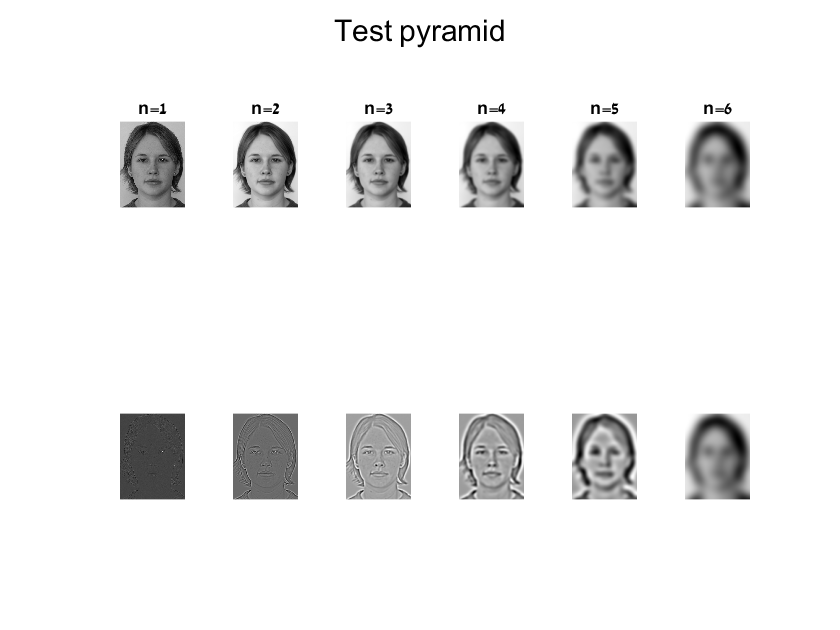


image = imread("data\Inputs\imgs\0004_6.png");
image_gray = im2double(rgb2gray(image));
n = 6;
[G, L] = pyrGen(image_gray, n);

figure();
sgtitle('Test pyramid');
for i=1:n
    subplot(2,6,i);
    imshow(G{i}, []);
    title(['n=', num2str(i)]);
    
    subplot(2,6,6 + i);
    imshow(L{i}, []);
end

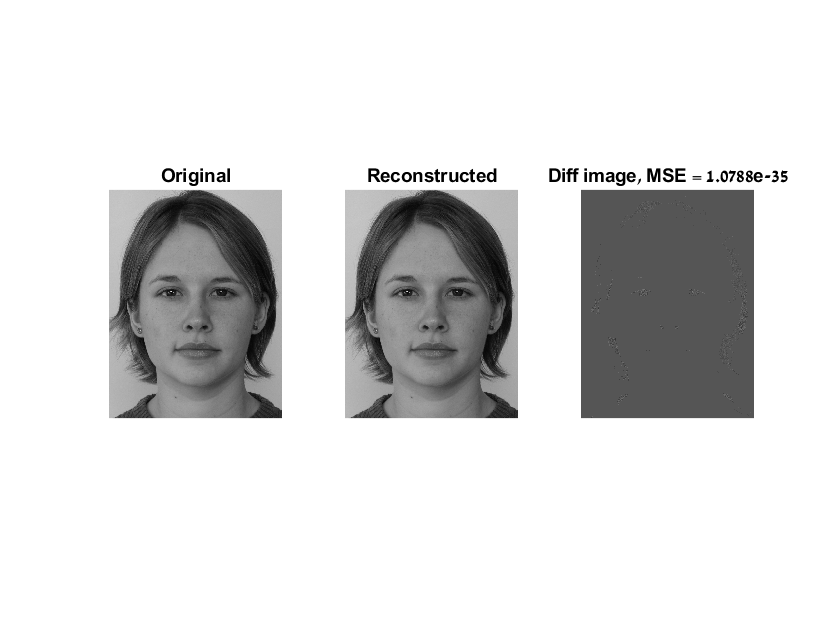


recon_image = imRecon(L);

sub_image = image_gray - recon_image;

mse = immse(image_gray, recon_image);

figure();
subplot(1,3,1);
imshow(image_gray, []);
title('Original');

subplot(1,3,2);
imshow(recon_image, []);
title('Reconstructed');

subplot(1,3,3);
imshow(sub_image, []);
title(['Diff image, MSE = ', num2str(mse)]);

## part c

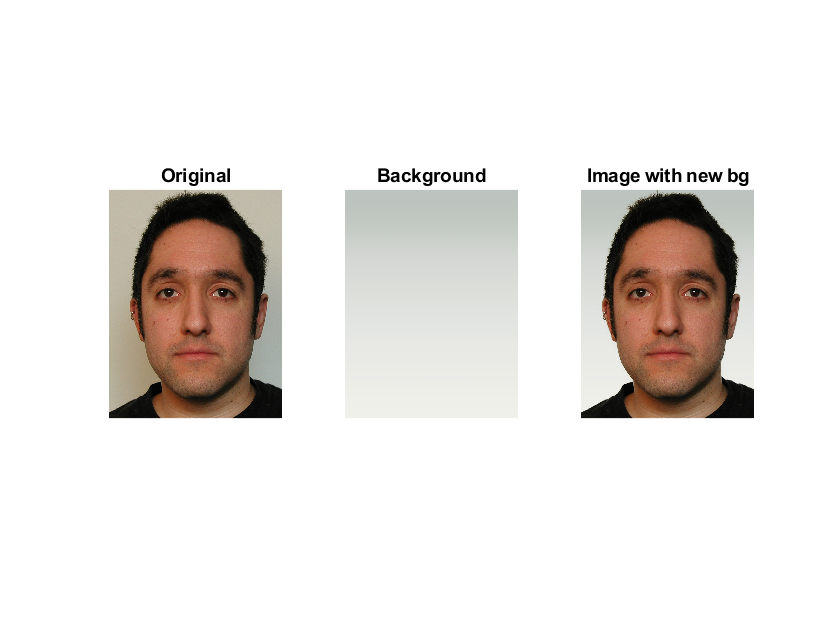

I = im2double(imread("data\Inputs\imgs\0006_001.png"));
E = im2double(imread("data\Examples\imgs\9.png"));
mask = im2double(imread("data\Inputs\masks\0006_001.png"));
bg = im2double(imread("data\Examples\bgs\9.jpg"));

I_new = changeBackground(I, mask, bg);
figure();
subplot(1,3,1);
imshow(I, []);
title('Original');

subplot(1,3,2);
imshow(bg, []);
title('Background');

subplot(1,3,3);
imshow(I_new, []);
title('Image with new bg');

## part d

n = 6;
I_r = I_new(:,:,1); % Red channel
I_g = I_new(:,:,2); % Green channel
I_b = I_new(:,:,3); % Blue channel
E_r = E(:,:,1); % Red channel
E_g = E(:,:,2); % Green channel
E_b = E(:,:,3); % Blue channel
[I_r_G, I_r_L] = pyrGen(I_r, n);
[I_g_G, I_g_L] = pyrGen(I_g, n);
[I_b_G, I_b_L] = pyrGen(I_b, n);
[E_r_G, E_r_L] = pyrGen(E_r, n);
[E_g_G, E_g_L] = pyrGen(E_g, n);
[E_b_G, E_b_L] = pyrGen(E_b, n);
S_I_r = {};
S_I_g = {};
S_I_b = {};
S_E_r = {};
S_E_g = {};
S_E_b = {};
for i=1:n
    S_I_r = [S_I_r; imgaussfilt(I_r_L{i} .^ 2, 2^(i+1))];
    S_I_g = [S_I_g; imgaussfilt(I_g_L{i} .^ 2, 2^(i+1))];
    S_I_b = [S_I_b; imgaussfilt(I_b_L{i} .^ 2, 2^(i+1))];
    S_E_r = [S_E_r; imgaussfilt(E_r_L{i} .^ 2, 2^(i+1))];
    S_E_g = [S_E_g; imgaussfilt(E_g_L{i} .^ 2, 2^(i+1))];
    S_E_b = [S_E_b; imgaussfilt(E_b_L{i} .^ 2, 2^(i+1))];
end
gain_r = {};
gain_g = {};
gain_b = {};
e = 10^-4;
for i=1:n
    gain_r = [gain_r; sqrt(S_E_r{i} ./ (S_I_r{i} + e))];
    gain_g = [gain_g; sqrt(S_E_g{i} ./ (S_I_g{i} + e))];
    gain_b = [gain_b; sqrt(S_E_b{i} ./ (S_I_b{i} + e))];
end

for i=1:n
    gain_r{i}(gain_r{i} < 0.9) = 0.9;
    gain_r{i}(gain_r{i} > 2.8) = 2.8;
    gain_g{i}(gain_g{i} < 0.9) = 0.9;
    gain_g{i}(gain_g{i} > 2.8) = 2.8;
    gain_b{i}(gain_b{i} < 0.9) = 0.9;
    gain_b{i}(gain_b{i} > 2.8) = 2.8;
end


## part e

O_r_L = {};
O_g_L = {};
O_b_L = {};
for i=1:n - 1
    O_r_L = [O_r_L; gain_r{i} .* I_r_L{i}];
    O_g_L = [O_g_L; gain_g{i} .* I_g_L{i}];
    O_b_L = [O_b_L; gain_b{i} .* I_b_L{i}];
end
O_r_L = [O_r_L; E_r_L{n}];
O_g_L = [O_g_L; E_g_L{n}];
O_b_L = [O_b_L; E_b_L{n}];


## part f

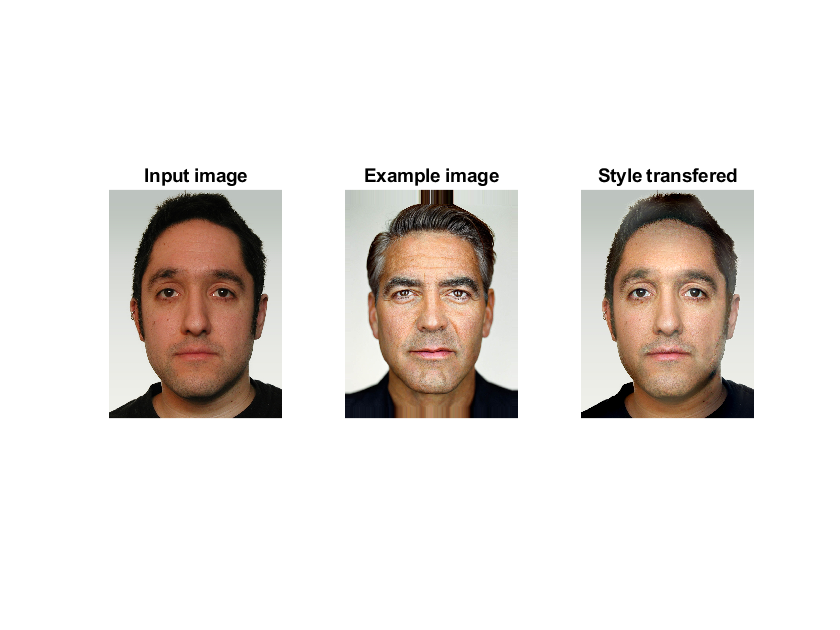

recon_r = imRecon(O_r_L);
recon_g = imRecon(O_g_L);
recon_b = imRecon(O_b_L);

recon_image = cat(3, recon_r, recon_g, recon_b);
recon_bg = changeBackground(recon_image, mask, bg);
figure();
subplot(1,3,1);
imshow(I_new, []);
title('Input image');
subplot(1,3,2);
imshow(E, []);
title('Example image');
subplot(1,3,3);
imshow(recon_bg, []);
title('Style transfered');